numc = 9;
denc = [1 7 0];
Te = 0.1;
t = [0:1:30];
td = [0:1:30];

Gd = tf(numc, denc);
G0 = feedback(Gd, 1)


G0 =
 
        9
  -------------
  s^2 + 7 s + 9
 
Continuous-time transfer function.


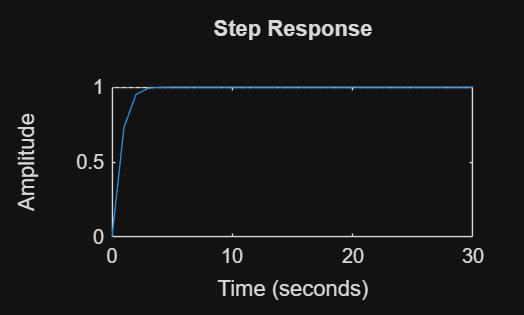

step(G0, t);

stepinfo(G0)

ans = struct with fields:
         RiseTime: 1.4008
    TransientTime: 2.5323
     SettlingTime: 2.5323
      SettlingMin: 0.9024
      SettlingMax: 0.9987
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9987
         PeakTime: 4.1512


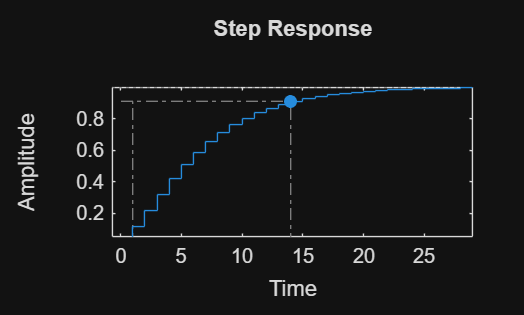


[numd, dend] = c2dm(numc, denc, Te, 'zoh');
[num, den] = feedback(numd, dend, 1, 1);
dstep(num, den, td);

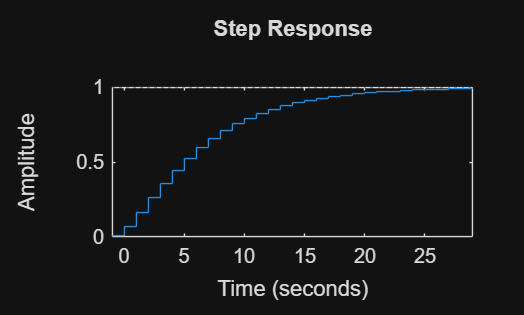

[numd, dend] = c2dm(numc, denc, Te, 'foh');
[num, den] = feedback(numd, dend, 1, 1);
dstep(num, den, td);

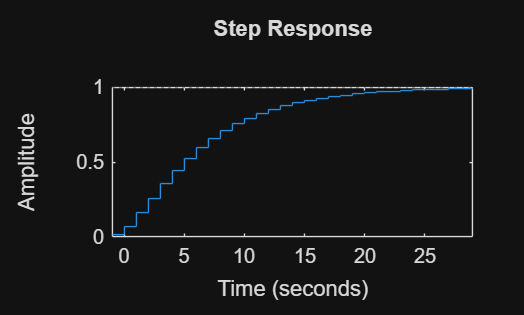

[numd, dend] = c2dm(numc, denc, Te, 'tustin');
[num, den] = feedback(numd, dend, 1, 1);
dstep(num, den, td);

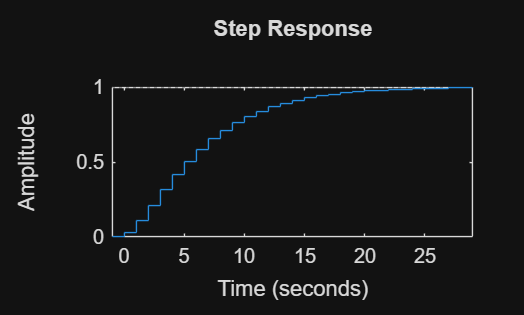

[numd, dend] = c2dm(numc, denc, Te, 'matched');
[num, den] = feedback(numd, dend, 1, 1);
dstep(num, den, td);